%extended grid square calculator
lat=34.24063

lat = 34.2406

long=-119.05522

long = -119.0552


long_mh=long+180                           %décallage de la grille

long_mh = 60.9448

lat_mh=lat+90

lat_mh = 124.2406


digit1=floor(long_mh/20)+1                %1er digit (tranche de 20 degrés longitude)

digit1 = 4

char1=char(digit1+64)                     %conversion en alphabétique

char1 = 'D'


digit2=floor(lat_mh/10)+1                 %2ème digit (tranche de 10 degrés latitude)

digit2 = 13

char2=char(digit2+64)                      %conversion en alphabétique

char2 = 'M'


digit3=floor(mod(long_mh,20)/2)            %3ème digit (tranche de 2 degré longitude)

digit3 = 0

char3=num2str(digit3)                      %conversion ASCII

char3 = '0'


digit4=floor(mod(lat_mh,10)/1)             %4ème digit (tranche de 1 degré latitude)

digit4 = 4

char4=num2str(digit4)                      %conversion ASCII

char4 = '4'


digit5=floor(mod(long_mh,2)*60/5)+1        %5ème digit (tranche de 5 minutes d'arc longitude)

digit5 = 12

char5=char(digit5+64)                      %conversion en alphabétique

char5 = 'L'


digit6=floor(mod(lat_mh,1)*60/2.5)+1     %6ème digit (tranche de 2.5 minutes d'arc latitude)

digit6 = 6

char6=char(digit6+64)                      %conversion en alphabétique

char6 = 'F'


digit7=floor(mod(long_mh,1/12)*120)            %7ème digit (tranche de 30 seconds longitude)

digit7 = 3

char7=num2str(digit7)                      %conversion ASCII

char7 = '3'


digit8=floor(mod(lat_mh,1/24)*240)             %8ème digit (tranche de 15 seconds latitude)

digit8 = 7

char8=num2str(digit8)                      %conversion ASCII

char8 = '7'



strcat(char1,char2,char3,char4,char5,char6,char7, char8) %concaténation et affichage

ans = 'DM04LF37'

wgs84 = wgs84Ellipsoid("m");

% 6  character grid square location around given lat long (red)
newlat1=lat-mod(lat,1/240)

newlat1 = 34.2375

newlat2=lat-mod(lat,1/240)+dms2degrees([0 0 15])

newlat2 = 34.2417

newlon1=long-mod(long,1/120)

newlon1 = -119.0583

newlon2=long-mod(long,1/120)+dms2degrees([0 0 30])

newlon2 = -119.0500


%2m 30s by 5 min square 8 charachter extended grid square around given lat
%long (green)
new2lat1=lat-mod(lat,1/24)

new2lat1 = 34.2083

new2lat2=lat-mod(lat,1/24)+dms2degrees([0 2 30])

new2lat2 = 34.2500

new2lon1=long-mod(long,1/12)

new2lon1 = -119.0833

new2lon2=long-mod(long,1/12)+dms2degrees([0 5 0])

new2lon2 = -119


% 7.5 arc second square around given lat long   gmted2010 (matlab default)
% terrain data (yellow)
new4lat1=lat-mod(lat,1/3600)

new4lat1 = 34.2406

new4lat2=lat-mod(lat,1/3600)+dms2degrees([0 0 7.5])

new4lat2 = 34.2426

new4lon1=long-mod(long,1/3600)

new4lon1 = -119.0553

new4lon2=long-mod(long,1/3600)+dms2degrees([0 0 7.5])

new4lon2 = -119.0532

leg1=distance(new4lat1,new4lon1,new4lat1,new4lon2,wgs84) %distance in meters

leg1 = 191.9241

leg2=distance(new4lat1,new4lon2,new4lat2,new4lon2,wgs84) %distance in meters

leg2 = 231.0974

sqrt(leg1*leg2)

ans = 210.6019


% 3 arc second square around given lat long   gmted2010 (matlab default)
% terrain data (black)
new5lat1=lat-mod(lat,1/3600)

new5lat1 = 34.2406

new5lat2=lat-mod(lat,1/3600)+dms2degrees([0 0 3])

new5lat2 = 34.2414

new5lon1=long-mod(long,1/3600)

new5lon1 = -119.0553

new5lon2=long-mod(long,1/3600)+dms2degrees([0 0 3])

new5lon2 = -119.0544

leg1=distance(new5lat1,new5lon1,new5lat1,new5lon2,wgs84) %distance in meters

leg1 = 76.7696

leg2=distance(new5lat1,new5lon2,new5lat2,new5lon2,wgs84) %distance in meters

leg2 = 92.4390

sqrt(leg1*leg2)

ans = 84.2408


% 1 arc second square around given lat long corresponding to (blue)

new3lat1=lat-mod(lat,1/3600)

new3lat1 = 34.2406

new3lat2=lat-mod(lat,1/3600)+dms2degrees([0 0 1])

new3lat2 = 34.2408

new3lon1=long-mod(long,1/3600)

new3lon1 = -119.0553

new3lon2=long-mod(long,1/3600)+dms2degrees([0 0 1])

new3lon2 = -119.0550

leg1=distance(new3lat1,new3lon1,new3lat1,new3lon2,wgs84) %distance in meters

leg1 = 25.5899

leg2=distance(new3lat1,new3lon2,new3lat2,new3lon2,wgs84) %distance in meters

leg2 = 30.8130

sqrt(leg1*leg2)

ans = 28.0802

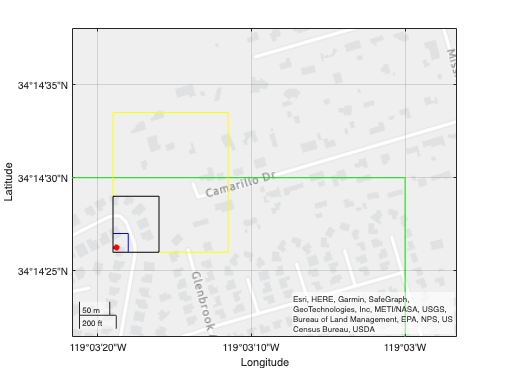

geoplot([new2lat1  new2lat1 new2lat2 new2lat2 new2lat1],[new2lon1 new2lon2  new2lon2 new2lon1 new2lon1],"red")
hold on
geoplot([newlat1  newlat1 newlat2 newlat2 newlat1],[newlon1 newlon2  newlon2 newlon1 newlon1],"green")
geoplot([new3lat1  new3lat1 new3lat2 new3lat2 new3lat1],[new3lon1 new3lon2  new3lon2 new3lon1 new3lon1],"blue")
geoplot([new4lat1  new4lat1 new4lat2 new4lat2 new4lat1],[new4lon1 new4lon2  new4lon2 new4lon1 new4lon1],"yellow")
geoplot([new5lat1  new5lat1 new5lat2 new5lat2 new5lat1],[new5lon1 new5lon2  new5lon2 new5lon1 new5lon1],"black")

geoscatter(lat, long,"red","filled")

maidenheadex(lat,long)

digit7 = 3

char7 = '3'

digit8 = 7

char8 = '7'

ans = 'DM04LF37'